$\Delta T_{lm}$ forklare på side 653

## Opgaver

Ogave 11.24

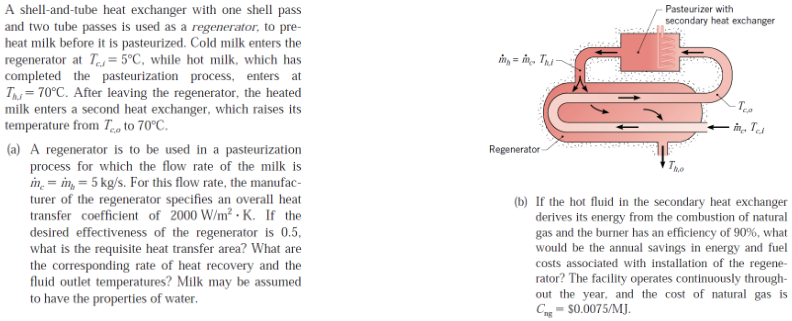

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'water'

fluid = 'water'


K = 273.15;
T_ci = 5 + K; %kold mælke start temperatur
T_hi = 70 + K; %varm mælk start temperatur
T_mi = (T_ci + T_hi)/2

T_mi =        310.65


% T_co = 70 + K; %kold mælk efter anden varme veksler
q_mh = 5; %kg/s %mass flow af varm mælk
q_mc = 5; %kg/s %mass flow af kold mælk
U = 2000; %W/m^2 % overall heat coeffecient
% q_overall = 2000; %W/m^2 % overall heat coeffecient
eta = 0.5; % ønskede effektivitet

% k = CoolProp.PropsSI('conductivity', 'P', P_atm, 'T', T_m, fluid)
c_p = 3860; %CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_mi, fluid) %specificHeat_p
% c_ph = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_hi, fluid) %specificHeat_p
% c_pc = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_ci, fluid) %specificHeat_p
% rho_h = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_hi, fluid) %Densitet
% rho_c = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_ci, fluid) %Densitet

% mu = CoolProp.PropsSI('viscosity', 'P', P_atm, 'T', T_m, fluid) %Dynamisk viscositet
% rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_m, fluid) %Densitet
% Pr = CoolProp.PropsSI('Prandtl', 'P', P_atm, 'T', T_m, fluid)
% nu = mu / rho

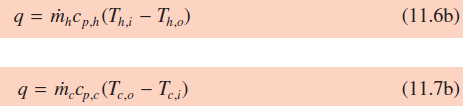

NTU (number of transfer units)

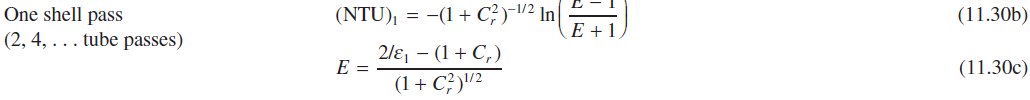

C_min = q_mh * c_p 

C_min =        19300


C_f = 1

C_f =      1


n = 2;
syms A eta_1
% eta_eq = eta == ( ( (1-eta_1 * C_min) / (1-eta_1) )^n - 1 ) *...
%                 ( ( (1-eta_1 * C_min) / (1-eta_1) )^n - C_min )^(-1);
% eta_1 = double(solve(eta_eq, eta_1))

eta_1 = eta % why?

eta_1 =           0.5


% E = (2/eta_1 - (1 + C_min)) / (1 + C_min^2)^(1/2)
E = (2/eta_1 - (1 + C_f)) / (1 + C_f^2)^(1/2) % why C_f???

E =        1.4142



% NTU = -(1 + C_min^2)^(-1/2) * log((E-1)/E+1)

A_eq = U * A / C_min == -(1 + C_min^2)^(-1/2) * log((E-1)/E+1);
A = double(solve(A_eq,A))

A =   -0.00012844




% syms T_ho T_co
% q_h = q_mh * c_ph * (T_hi - T_ho)
% q_c = q_mc * c_pc * (T_co - T_ci)
% 
% % q_hi = q_c + q_overall * eta
% % q_hi = q_mh * c_ph * (T_hi - T_co)
% q_eq = q_overall * eta == q_mh * c_ph * (T_hi - T_co)
% 
% [T_ho_sol, T_co_sol] = solve([q_h == q_c, q_eq], [T_ho, T_co]);
% T_ho = double(T_ho_sol) - K
% T_co = double(T_co_sol) - K

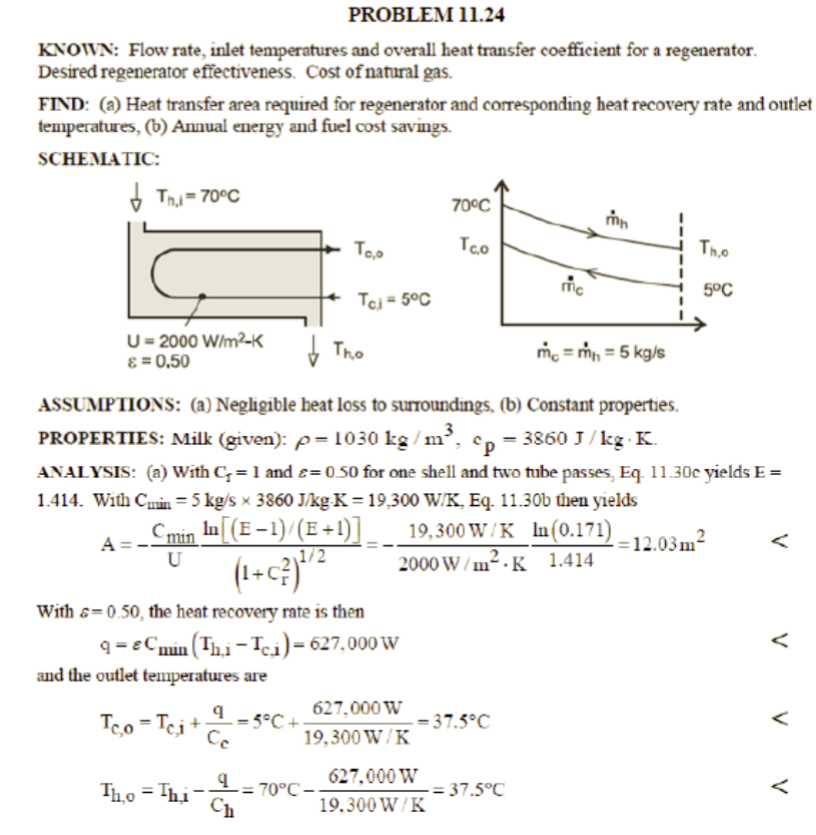

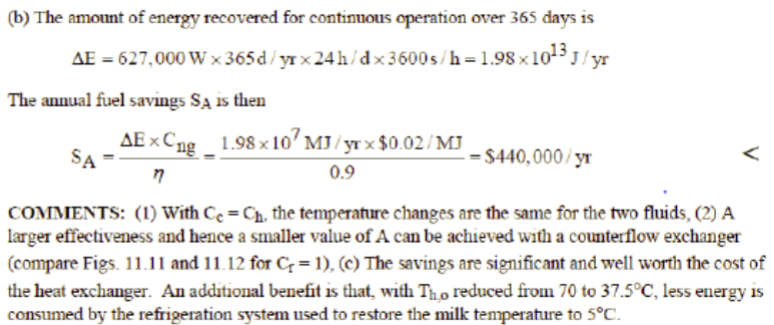

Opgave 11.39